# **META 2 **

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% AUDIO_DIGIT_ANALYSIS_META2.M
%
% Script for Audio Digit Analysis - Meta 2
% Tasks:
% 10) Load data structure from previous meta (finalAudioData.mat).
% 11) For each preprocessed signal, calculate the Fourier coefficients (FFT)
%     and store them in the data structure.
% 12) For each digit, calculate the normalized median amplitude spectrum (|FFT|/N)
%     for positive frequencies and compute the 25th and 75th percentiles.
%     The results are plotted (see Fig. 4).
% 13) Extract spectral features for each signal:
%       - Maximum spectral amplitude and its frequency.
%       - Spectral centroid.
%       - Spectral edge frequency (frequency below which 90% of energy is contained).
%       - Spectral bandwidth.
% 14) Visualize the spectral features using boxplots to aid digit discrimination.
% 15) Update the data structure file (finalAudioData.mat).
%
% Authors: [Teodoro Marques, Bernardo Direito]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;

%% INITIAL PARAMETERS
participantID = 40;             % Unique participant identifier
digitNumbers = 0:9;             % Digits from 0 to 9

## 10.

%% STAGE 10: LOAD DATA STRUCTURE FROM PREVIOUS META
try
    load('finalAudioData.mat', 'metadataTable');
    disp('Data structure loaded from finalAudioData.mat');
catch ME
    error('Error loading finalAudioData.mat: %s', ME.message);
end

Data structure loaded from finalAudioData.mat



% Verify that the table contains the preprocessed signals
if ~istable(metadataTable) || ~any(strcmp(metadataTable.Properties.VariableNames, 'PreprocessedAudioSignal'))
    error('Preprocessed audio signal column is missing.');
end

% Total number of recordings
totalRecordings = height(metadataTable);

## 11.

%% STAGE 11: FOURIER COEFFICIENT CALCULATION
% Pre-allocate cell array for Fourier coefficients
fourierCoeffs = cell(totalRecordings, 1);

for i = 1:totalRecordings
    signal = metadataTable.PreprocessedAudioSignal{i};
    if isempty(signal)
        fourierCoeffs{i} = [];
        continue;
    end
    try
        coeffs = fft(signal);
        fourierCoeffs{i} = coeffs;
    catch coeffError
        warning('FFT calculation error for recording %d: %s', i, coeffError.message);
        fourierCoeffs{i} = [];
    end
end

% Add Fourier coefficients to the table
metadataTable.FourierCoeffs = fourierCoeffs;

## 12.

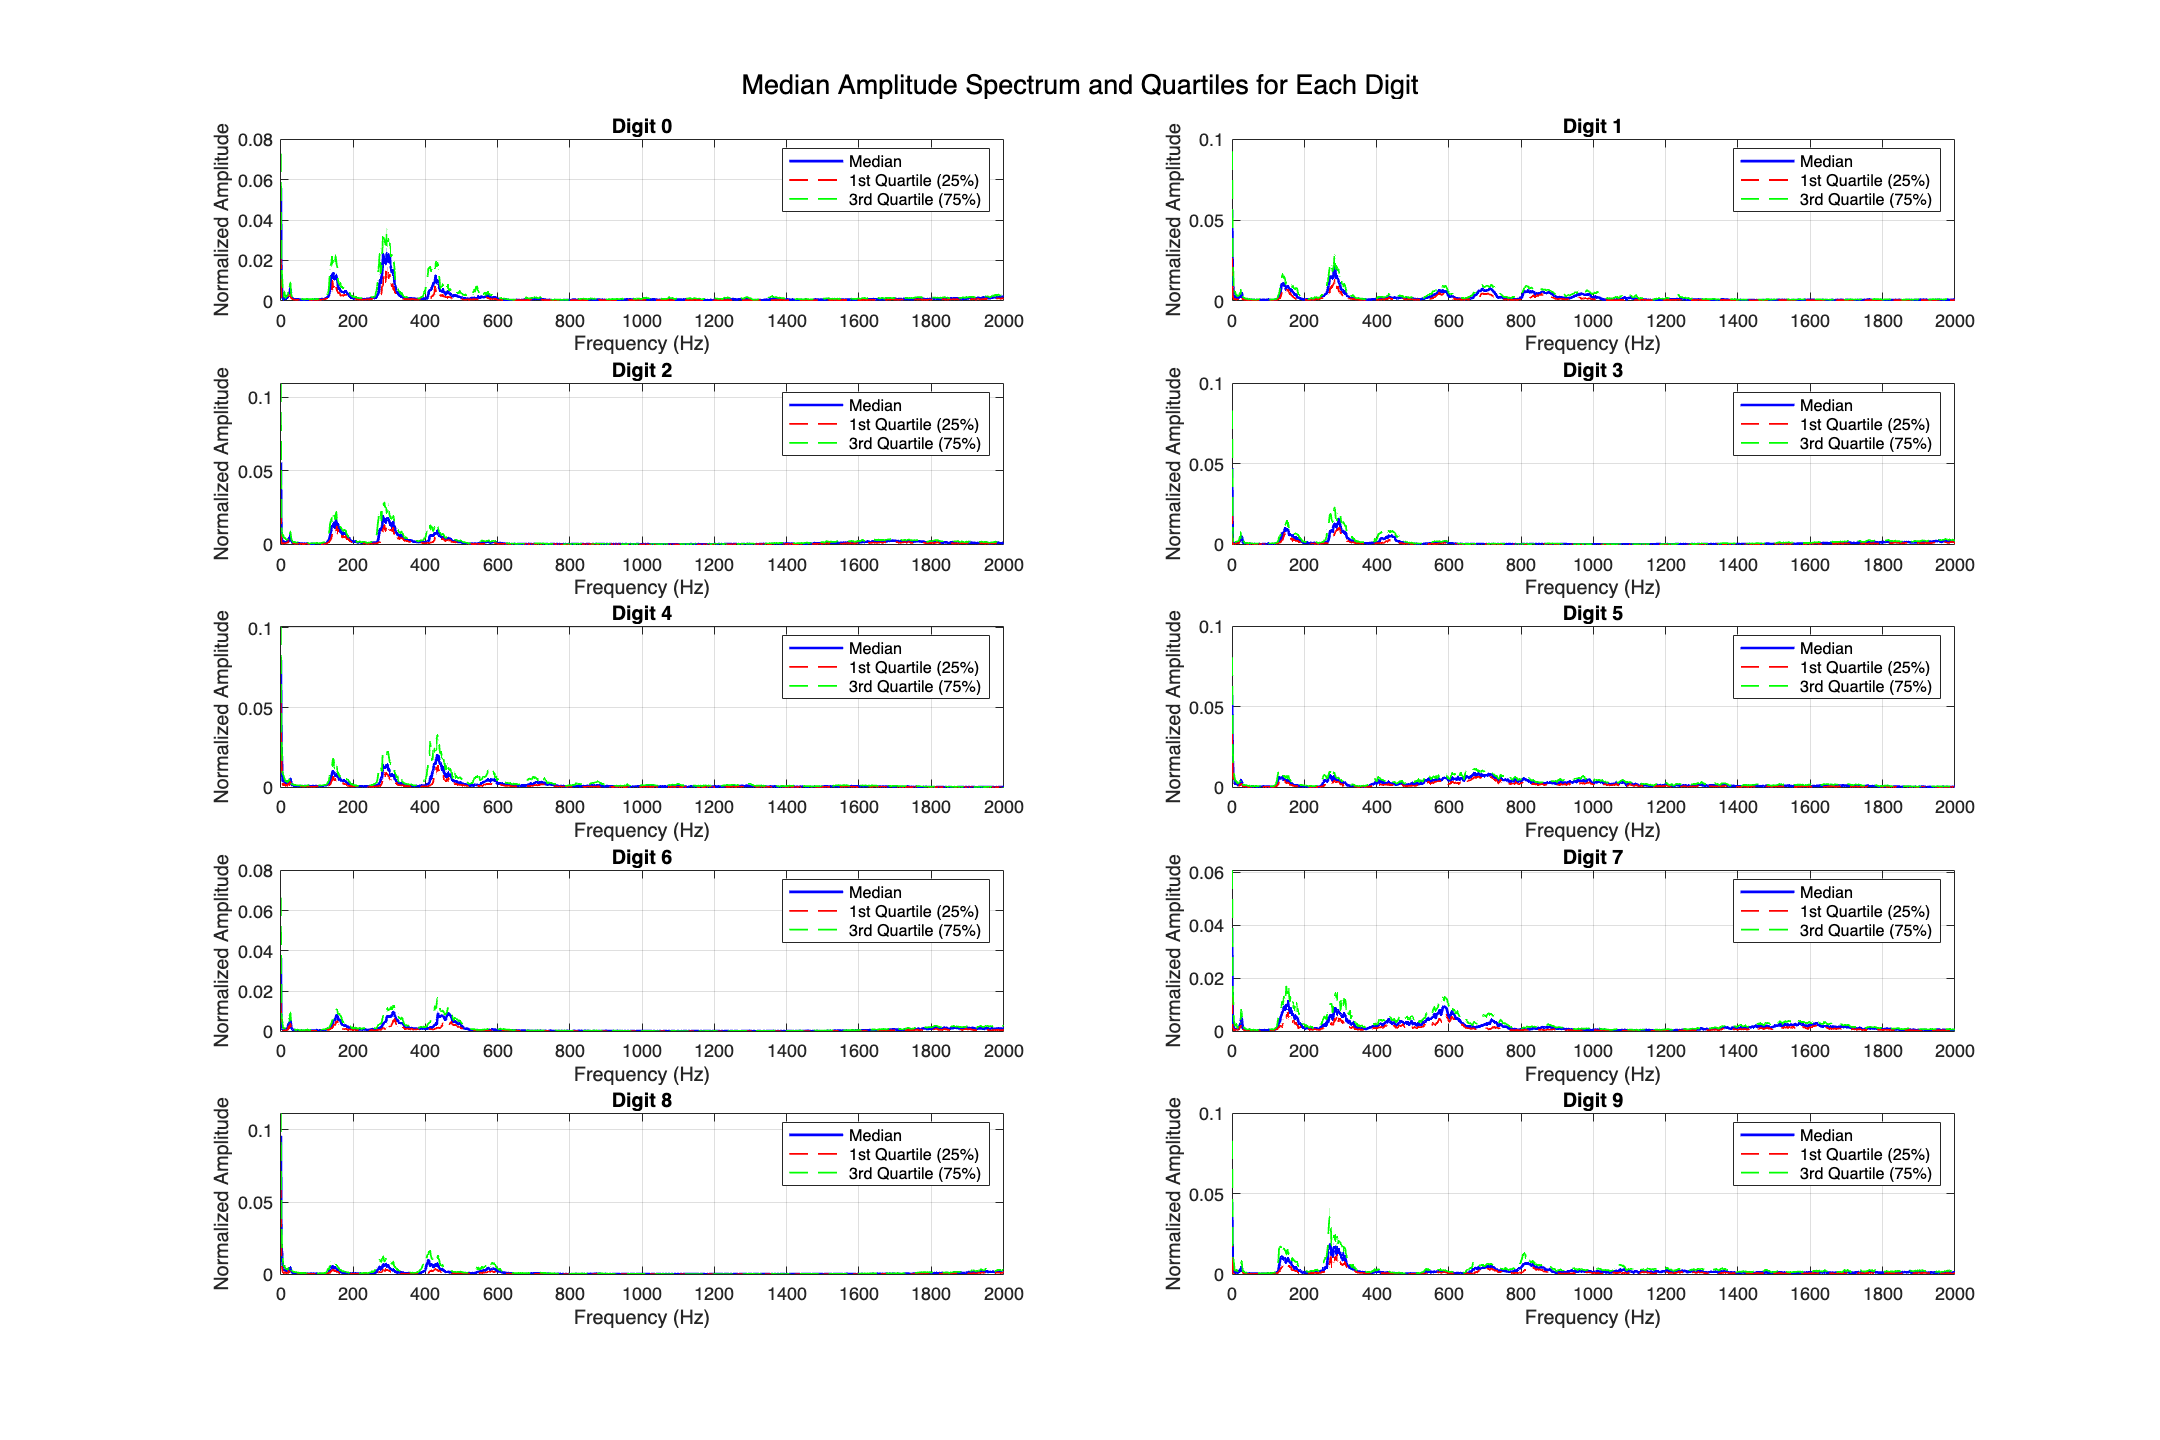

%% STAGE 12: MEDIAN AMPLITUDE SPECTRUM CALCULATION AND PLOTTING
uniqueDigits = unique(metadataTable.DigitValue);
figure('Position', [100, 100, 1200, 800]);

for idx = 1:length(uniqueDigits)
    d = uniqueDigits(idx);
    indices = find(metadataTable.DigitValue == d);
    spectra = [];
    
    for j = 1:length(indices)
        sig = metadataTable.PreprocessedAudioSignal{indices(j)};
        if isempty(sig)
            continue;
        end
        N = length(sig);
        Y = fft(sig);
        magSpec = abs(Y) / N;
        posFreqCount = floor(N/2) + 1;
        magSpec = magSpec(1:posFreqCount);
        spectra = [spectra, magSpec];  %#ok<AGROW>
    end
    
    if ~isempty(spectra)
        medianSpec = median(spectra, 2);
        quantile25 = quantile(spectra, 0.25, 2);
        quantile75 = quantile(spectra, 0.75, 2);
        
        fs = metadataTable.SamplingRate(indices(1));
        f = linspace(0, fs/2, size(medianSpec, 1));
        
        subplot(5,2,idx);
        plot(f, medianSpec, 'b', 'LineWidth', 1.5); hold on;
        plot(f, quantile25, 'r--', 'LineWidth', 1);
        plot(f, quantile75, 'g--', 'LineWidth', 1);
        title(sprintf('Digit %d', d));
        xlabel('Frequency (Hz)');
        ylabel('Normalized Amplitude');
        legend('Median', '1st Quartile (25%)', '3rd Quartile (75%)');
        grid on;
        
        xlim([0, 2000]);
   
    end
end
sgtitle('Median Amplitude Spectrum and Quartiles for Each Digit');

## 13.

%% STAGE 13: SPECTRAL FEATURE EXTRACTION
% Pre-allocate feature arrays
SpecMaxAmp = zeros(totalRecordings, 1);
SpecMaxFreq = zeros(totalRecordings, 1);
SpecCentroid = zeros(totalRecordings, 1);
SpecEdgeFreq = zeros(totalRecordings, 1);
SpecBandwidth = zeros(totalRecordings, 1);

for i = 1:totalRecordings
    signal = metadataTable.PreprocessedAudioSignal{i};
    if isempty(signal)
        continue;
    end
    
    N = length(signal);
    fs = metadataTable.SamplingRate(i);
    Y = fft(signal);
    magSpec = abs(Y) / N;
    posFreqCount = floor(N/2) + 1;
    magSpec = magSpec(1:posFreqCount);
    f = linspace(0, fs/2, posFreqCount)';
    
    % 1. Maximum amplitude and its frequency
    [maxAmp, idxMax] = max(magSpec);
    SpecMaxAmp(i) = maxAmp;
    SpecMaxFreq(i) = f(idxMax);
    
    % 2. Spectral centroid (weighted mean frequency)
    if sum(magSpec) > 0
        SpecCentroid(i) = sum(f .* magSpec) / sum(magSpec);
    else
        SpecCentroid(i) = 0;
    end
    
    % 3. Spectral edge frequency (frequency below which 90% of energy is contained)
    cumulativeEnergy = cumsum(magSpec);
    totalEnergy = cumulativeEnergy(end);
    idxEdge = find(cumulativeEnergy >= 0.9 * totalEnergy, 1);
    SpecEdgeFreq(i) = f(idxEdge);
    
    % 4. Spectral bandwidth (standard deviation of frequencies weighted by the spectrum)
    if sum(magSpec) > 0
        SpecBandwidth(i) = sqrt(sum(((f - SpecCentroid(i)).^2) .* magSpec) / sum(magSpec));
    else
        SpecBandwidth(i) = 0;
    end
end

% Update table with spectral features
metadataTable.SpecMaxAmp = SpecMaxAmp;
metadataTable.SpecMaxFreq = SpecMaxFreq;
metadataTable.SpecCentroid = SpecCentroid;
metadataTable.SpecEdgeFreq = SpecEdgeFreq;
metadataTable.SpecBandwidth = SpecBandwidth;

## 14.

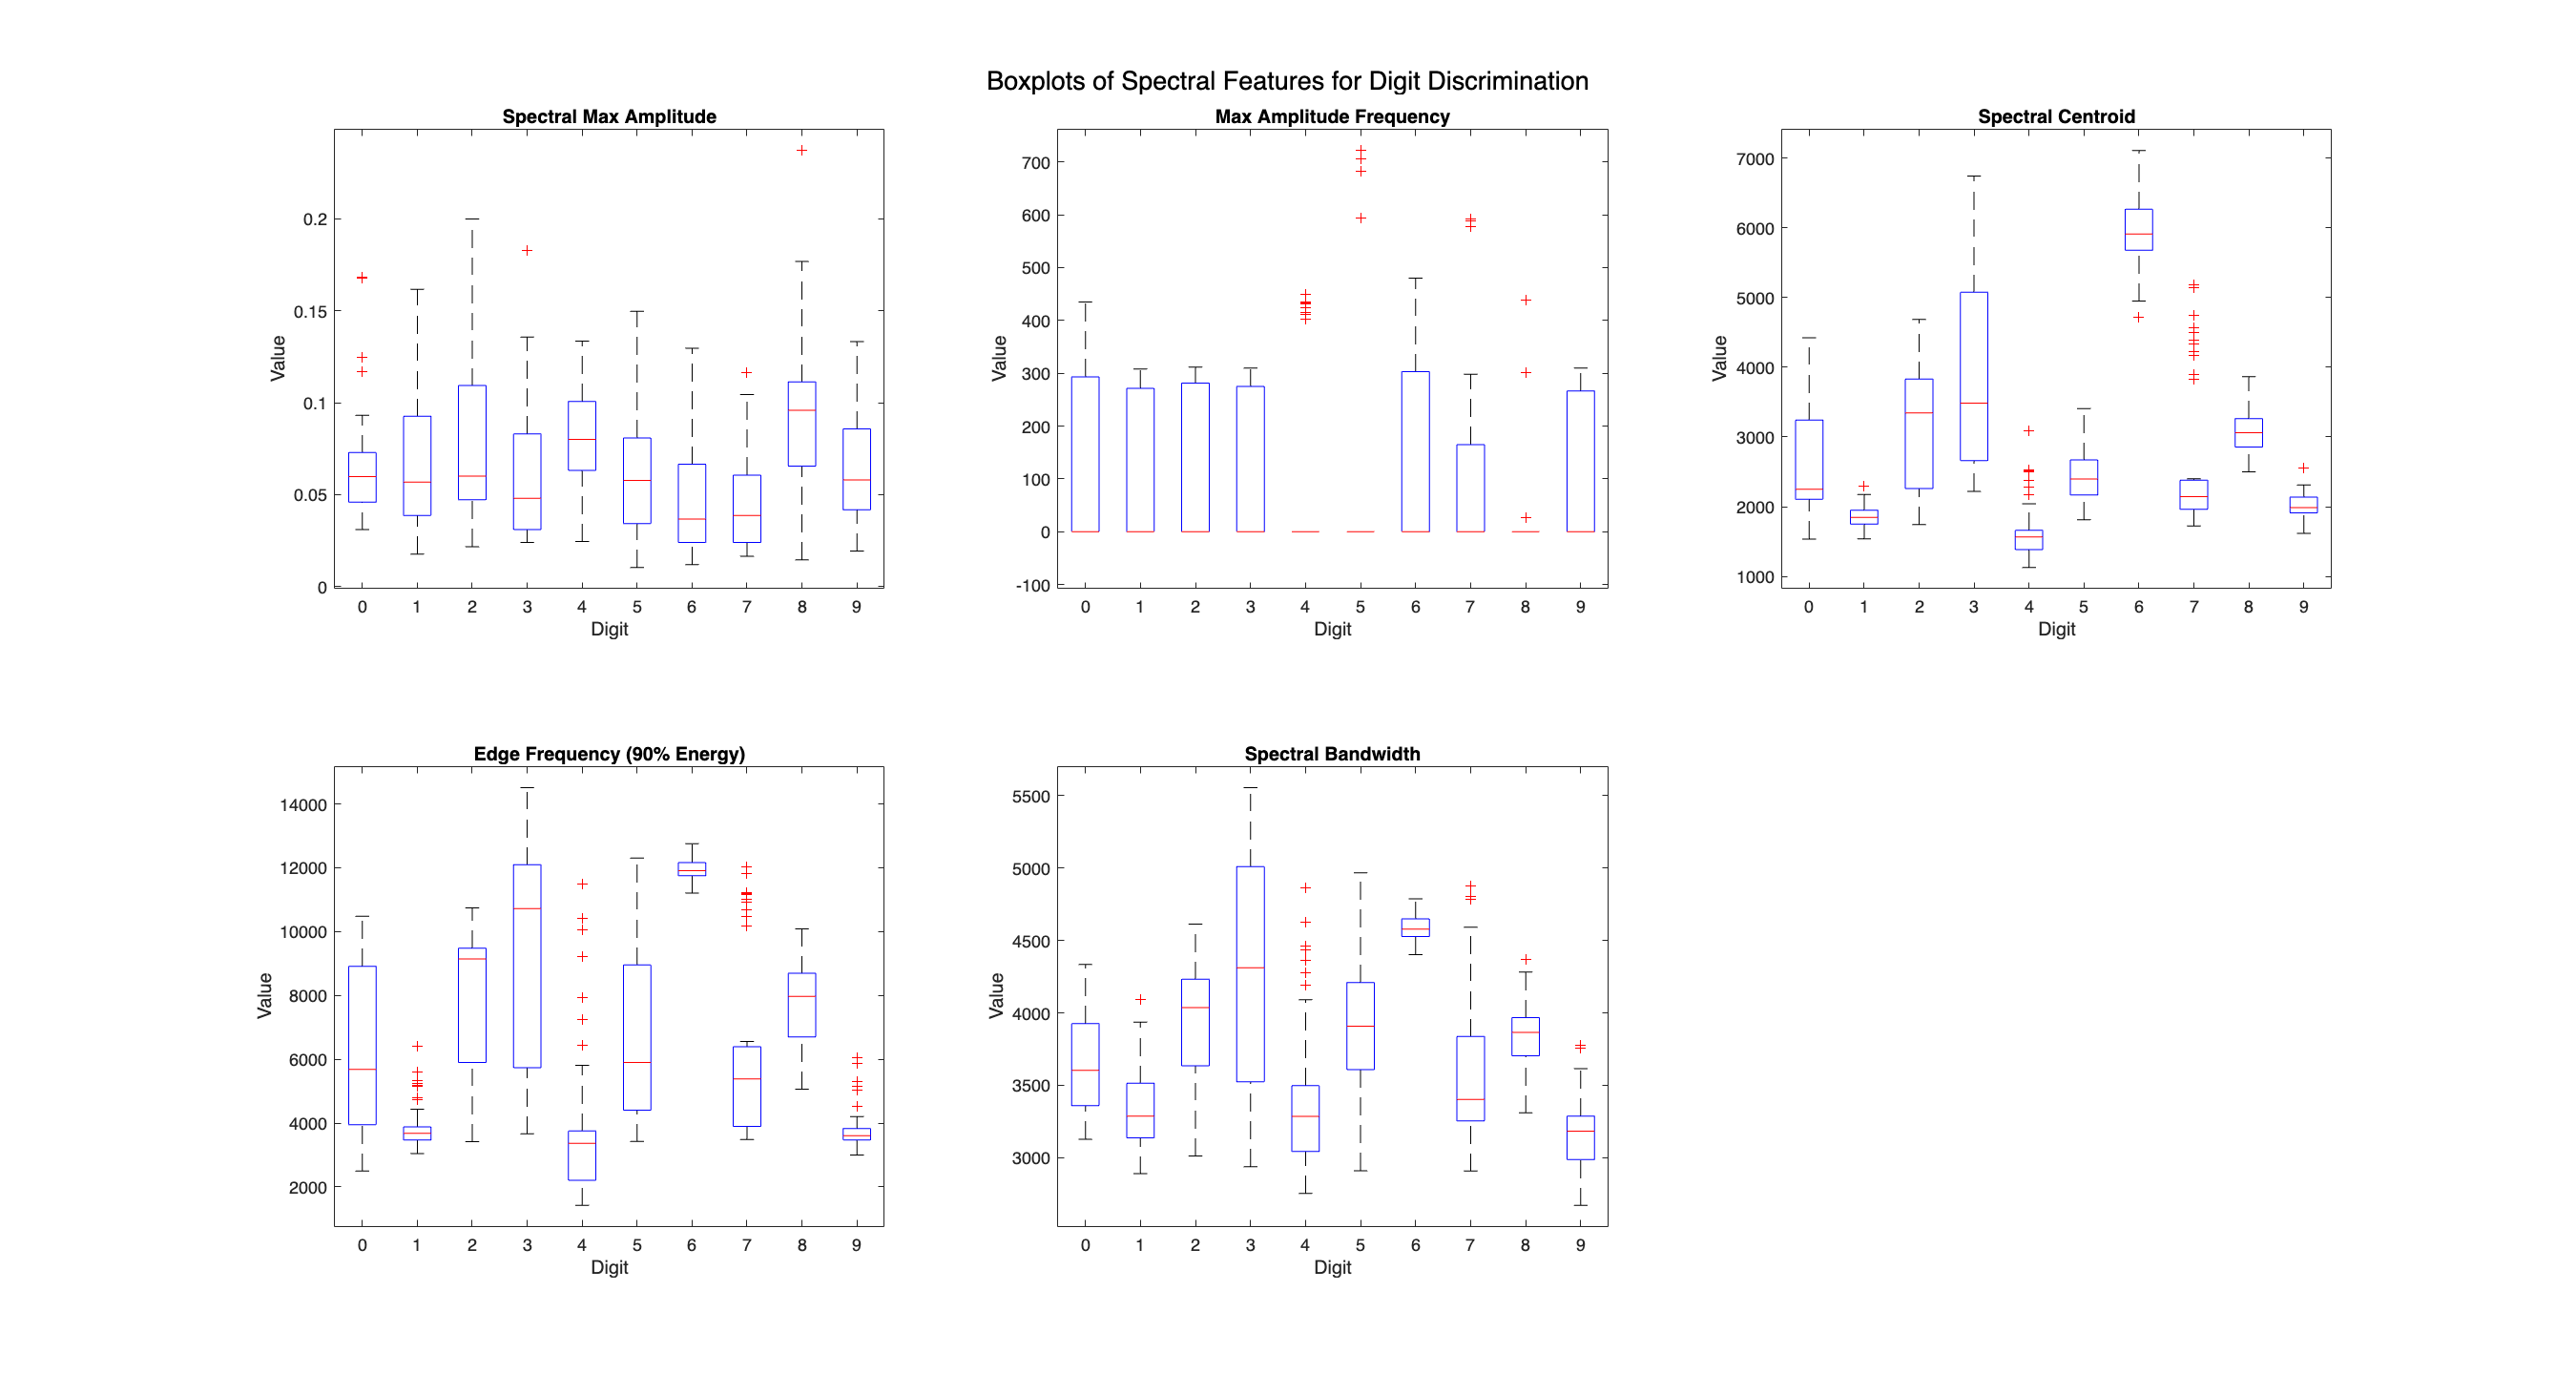

%% STAGE 14: GRAPHICAL REPRESENTATION OF SPECTRAL FEATURES
figure('Position', [100, 100, 1500, 800]);

% Titles for each subplot
titles = {'Spectral Max Amplitude', 'Max Amplitude Frequency', ...
          'Spectral Centroid', 'Edge Frequency (90% Energy)', ...
          'Spectral Bandwidth'};

% Ensure DigitValue is numeric
if iscell(metadataTable.DigitValue)
    digitVec = cellfun(@str2double, metadataTable.DigitValue);
else
    digitVec = metadataTable.DigitValue;
end

% Prepare spectral feature data in a cell array
specFeatures = {metadataTable.SpecMaxAmp, metadataTable.SpecMaxFreq, ...
                metadataTable.SpecCentroid, metadataTable.SpecEdgeFreq, ...
                metadataTable.SpecBandwidth};

for j = 1:5
    subplot(2,3,j);
    boxData = [];
    groupData = [];
    % Loop sobre os dígitos de 0 a 9
    for d = 0:9
        digitIndices = (digitVec == d);
        data = specFeatures{j}(digitIndices);
        data = data(:);  % Garante que 'data' seja um vetor coluna
        boxData = [boxData; data];
        groupData = [groupData; repmat(d, numel(data), 1)];
    end
    % Cria o boxplot utilizando arrays numéricos
    boxplot(boxData, groupData, 'Labels', cellstr(num2str((0:9)')));
    title(titles{j});
    xlabel('Digit');
    ylabel('Value');
end
sgtitle('Boxplots of Spectral Features for Digit Discrimination');

## 15.

%% STAGE 15: FINAL DATA STRUCTURE UPDATE
try
    save('finalAudioData.mat', 'metadataTable');
    disp('finalAudioData.mat updated with complete data structure.');
catch ME
    warning(ME.identifier, 'Error saving finalAudioData.mat: %s', ME.message);
end

finalAudioData.mat updated with complete data structure.
